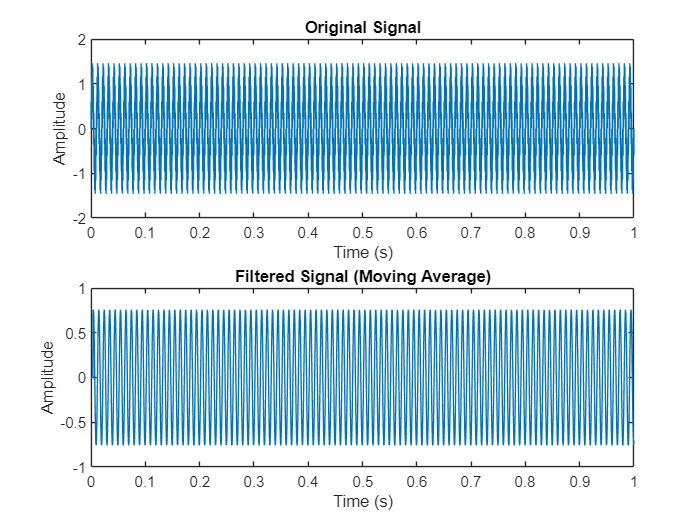

cutoff_frequency = 1000;
sampling_rate = 5000;   
filter_order = 20;    

t = 0:1/sampling_rate:1; 
input_signal = sin(2*pi*100*t) + 0.5*sin(2*pi*1000*t); 
filter_coefficients = ones(1, filter_order) / filter_order;

filtered_signal = zeros(size(input_signal));

for n = filter_order:length(input_signal)
    filtered_signal(n) = filter_coefficients * input_signal(n-filter_order+1:n)';
end

figure;
subplot(2,1,1);
plot(t, input_signal);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, filtered_signal);
title('Filtered Signal (Moving Average)');
xlabel('Time (s)');
ylabel('Amplitude');